# (4). NMR Signal Integration

### Introduction

In the previous examples we have introduced the processing steps that need to be applied to the Free Induction Decay (FID) to generate high quality NMR spectra in the frequency domain. By taking the Fourier transform of the FID, we are presenting the information in a way that is directly interpretable because frequencies are clearly separated. By analyzing intensity, position, and appearance of specific peaks, chemists can determine structures of their molecules.

The position of each peak is called ***chemical shift***. It provides information about chemical neighborhood of the nucleus. Its units are ppm: parts per million shifts in frequency relative to the frequency of a reference substance, commonly tetramethylsilane. This unit system standardizes the NMR data, allowing for comparison across different magnetic field strengths. The definition is as follows:  


$$\delta = \frac{\nu_{\text{sample}} - \nu_{\text{reference}}}{\nu_{\text{reference}}} \times 10^6
$$


**Sample frequency**: the frequency at which the nucleus resonates in the magnetic field.

**Reference frequency:** the frequency of some standard reference compound.

The sample used in this example is ethyl crotonate (Figure 1). This data is kindly provided by Prof. Ilya Kuprov, University of Southampton. The labelled peaks demonstrate how signals in the NMR spectrum give insight into the structure of the sample. For example, signal 1 belongs to the rightmost methyl group. It is a triplet because there are two protons next door. It has a low chemical shift (*i.e.* it is highly shielded by the surrounding electrons) because it is far from electronegatve atoms such as oxygen.

### 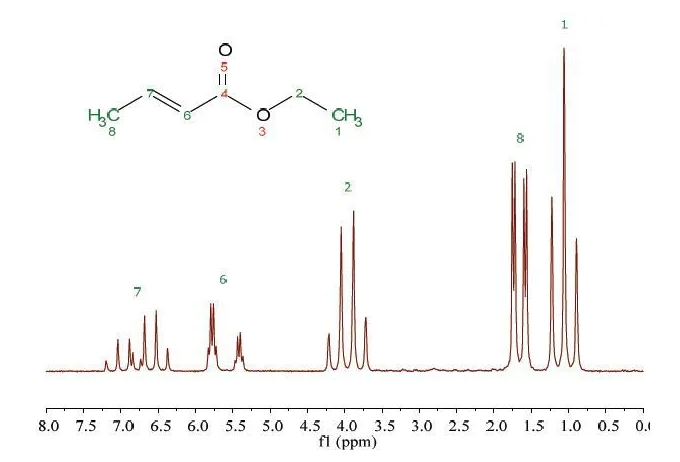

**Figure 1. **1H NMR Spectrum of *25% ethyl crotonate in CDCl3 (https://www.azom.com/article.aspx?ArticleID=11352).*

Signal 2 belongs to the methylene group. It is a quartet because there are three protons on the methyl next door. 

We will not cover quantum mechanical reasons why NMR signals appear as clusters called ***multiplets*** in this example. However, we will make use of the fact that area under each signal is proportional to the number of nuclei contributing to the signal. Therefore, integration allows for quantitative analysis of mixtures. For example, in a molecule like ethanol, integration can reveal hydrogen atom counts in different functional groups (CH3, CH2, OH). Let us now demonstrate by numerical integration that the area of the CH2 group signal is 2/3 of the area of the CH3 group signal.

### Experimental data import and plotting

The NMR spectrum of ethyl crotonate has already been processed and exported into a file that we will now load, Fourier transform, and normalise out arbitrary instrumental measurement units:

% Load the file
load('ethyl_crotonate_processed.mat','time_axis','ppm_axis','fid');

% Fourier transform and take the real part
spectrum=real(fft(fid));

% Normalise the spectrum
spectrum=spectrum/max(abs(spectrum));

We need the figure to pop out of this example to allow us to click on it:

% Make the figure pop out
figure(); set(gcf,'Visible','on')

% Plot the spectrum 
plot(ppm_axis,spectrum); ylabel('signal, a.u.');
set(gca,'XDir','reverse'); title('Figure 2'); 
xlabel('chemical shift, ppm'); grid;

### **Signal integration**

Click once on the left of a particular signal, and once on the right.

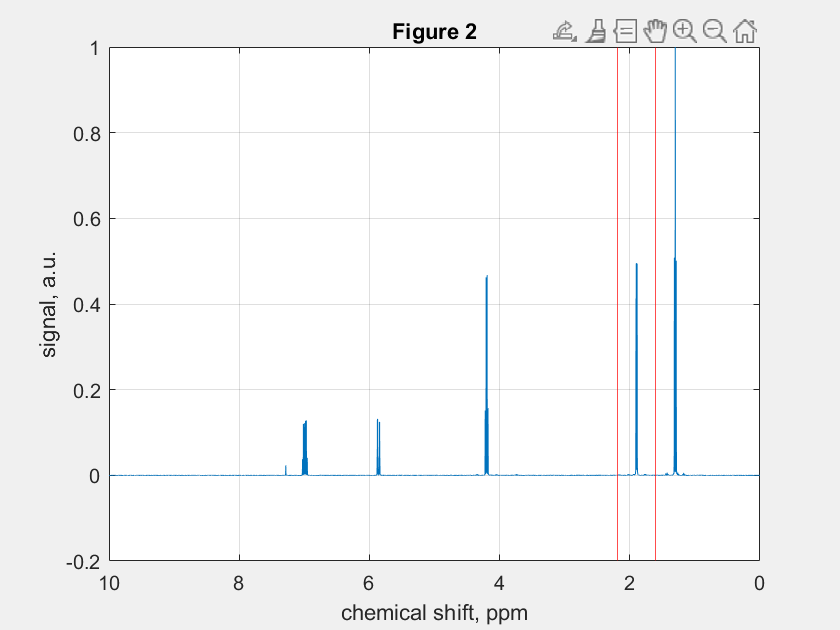

% Select first boundary of integration 
[x1,~]=ginput(1); xline(x1,'-r');

% Select second boundary of integration 
[x2,~]=ginput(1); xline(x2,'-r');

We then run the integration using [trapezium rule](https://www.mathworks.com/help/matlab/ref/trapz.html). Note the power of logical indexing:

% Find array index range
idx_range=(ppm_axis>=min([x1 x2]))&...
          (ppm_axis<=max([x1 x2]));

% Run the integration
integral=trapz(ppm_axis(idx_range),spectrum(idx_range));

% Display the result
fprintf('Integral between %.2f and %.2f ppm: %.4f\n',x1,x2,integral);

Integral between 2.19 and 1.61 ppm: 0.0038


If you run this example twice and integrate the signals of methyl and methylene groups, you should see that the areas have the expected 3:2 ratio:

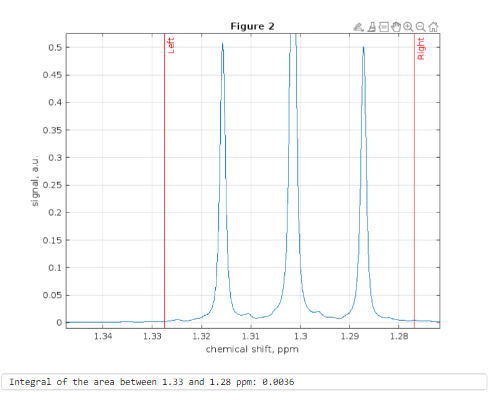                     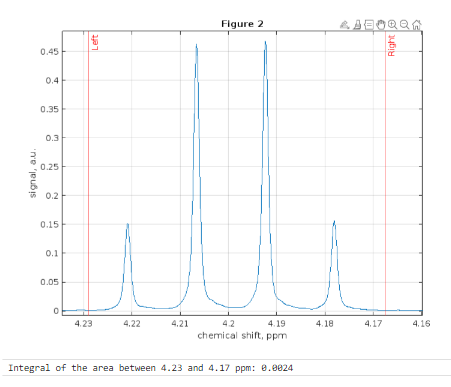

### Summary

In this example we took the user input for the numerical integration ranges, found the corresponding array index extents and simply called the built-in trapezium rule integrator. For a single spectrum, this is not a big deal, but when thousands of spectra are involved (for example in reaction kinetics research), such automated quantification becomes important.